%these are the only datasets that are usable
outputnames = [...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",...
    ];

inputdirs = [...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\BallenyIslands2015\\",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\casey2017\\",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\kerguelen2015\\",
    ];

outputdir = "D:\\Whale Data\\Raw Audio Data\\";

dtformat = "yyyyMMdd_HHmmss";

%create spectrograms
for idx = 1:numel(outputnames)
    sc = SpectrogramCreator(outputnames(idx));
    sc.create(16, 0.1, 1000, AudioDataConverter.L, 10, 150);
end

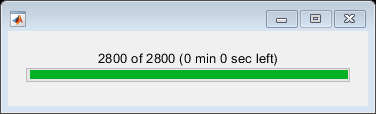

%create gmms
for idx = 1:numel(outputnames)
    gc = SEGMMCreator(outputnames(idx), 62.5);
    gc.create();
end

%convert annotations
for fidx = 1:numel(inputdirs)
    ac = AnnotationConverter(inputdirs(fidx), outputnames(fidx));
    ac.convert();
end

Error using load
Unable to find file or directory 'D:\Whale Data\Raw Audio Data\BallenyIslands2015\segmm\NoiseEstimate.mat'.

Error in AnnotationConverter/calcANR (line 114)
            noiseEstimate = load(noisepath).noiseEstimates;

Error in AnnotationConverter/convert (

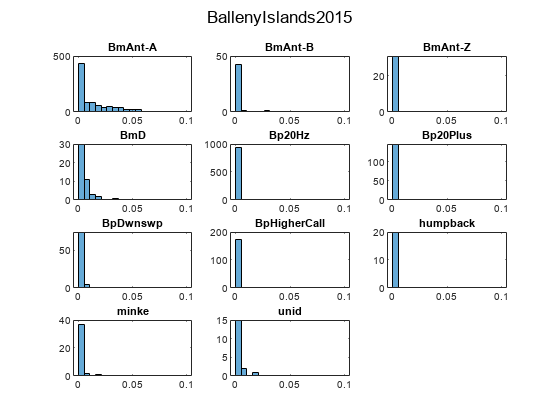

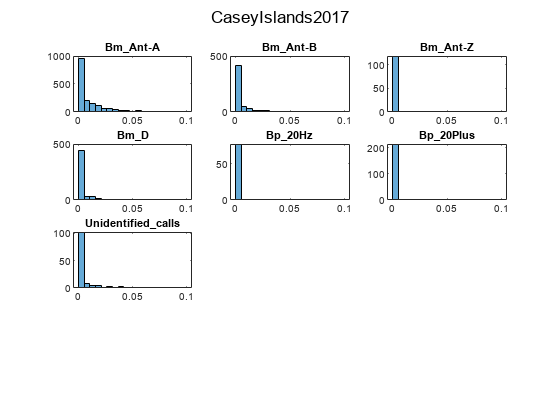

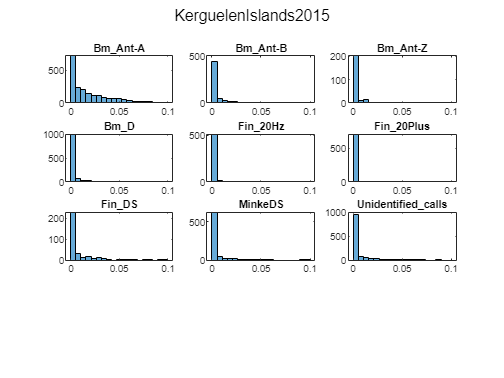

%plot annotation significance
%convert annotations
for fidx = 1:numel(outputnames)
    path = outputdir + outputnames(fidx) + "\\annotations\\annotations.mat";
    T = load(path).annotationTable;
    cat = unique(T.Annotation);
    b = linspace(0, 0.1, 20);
    figure
    hold on
    for c = 1:numel(cat)
        subplot(4,3,c)
        idx = T.Annotation == cat(c);
        histogram(T.AnnotationSignificance(idx), b)
        title(cat(c), "Interpreter","none");
%         set(gca, "Yscale", "log")
    end
    hold off
    sgtitle(outputnames(fidx))
end

%plot annotations
for fidx = 1:numel(outputnames)

    pathformatted = outputdir + outputnames(fidx);
    spectropath = pathformatted + "\\spectrograms\\";
    annpath = pathformatted + "\\annotations\\";
    annotationTable = load(annpath + "annotations.mat").annotationTable;
    load(spectropath + "filterbank.mat")

    threadidx = ThreadIdx(size(annotationTable, 1), 6);

    fbfs = fb.getSSamplingFreq();
    spmd %for i = 1
        counter = 1;
        while ~threadidx.complete(spmdIndex)
            try
            idx = threadidx.next(spmdIndex);
            row = annotationTable(idx, :);
            name = extractBefore(row.File, ".wav");
            spectroname = name + ".mat";        
            s = load(spectropath + spectroname).s;
            s = s.^2;
            logs = log(s);
            fig = figure("Visible", "off");
            fb.plotS(s, true);
            t = [row.StartIdx, row.EndIdx]/1000;
            tlims = [max(row.StartIdx-500, 0), min(row.EndIdx+500, AudioDataConverter.L)]/1000;
            fbox = [row.StartFrequency, row.StartFrequency, row.EndFrequency, row.EndFrequency];
            tbox = [t(1), t(2), t(2), t(1)];
            xlim(tlims);
            clim([min(logs, [],"all"), max(logs, [],"all")])
            hold on
            fill( tbox, fbox, 'r', "FaceAlpha",0.1, "EdgeAlpha",0.8);
            hold off
            fname = sprintf("%s (%s) (%d)", row.Annotation, extractBefore(row.File, ".wav"), counter);
            title(fname, "Interpreter","none");
            saveas(fig, annpath + fname + ".png")
            close(fig);
            counter = counter + 1;
            catch e
                disp(getReport(e, "extended"))
            end
        end        
    end
    
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to the parallel pool (number of workers: 6).


Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to the parallel pool (number of workers: 6).


%create contours
for idx = 1:1%1:numel(outputnames)
    cc = ContourCreator(outputnames(idx));
    cc.create();
end

%label the contours
for idx = 1:1%1:numel(outputnames)
    cl(idx) = ContourLabeler(outputnames(idx), 62.5, 1000, 0.005);
    cl(idx).match();
end

    20

    40

    60

    80

   100



%get detection stats
for idx = 1:1%1:numel(outputnames)
    disp "------------------------"
    disp (outputnames(idx))
    ann = groupcounts(cl(idx).annotationTable, "Annotation");
    statTable = cl(idx).contourTable(:, ["Annotation", "Duration", "BLSNR"]);
    statTable.BLSNR(isinf(statTable.BLSNR)) = nan;
    annstats = grpstats(statTable, "Annotation", "mean")
    Annotation = "Unmatched";
    GroupCount = 0;
    Percent = 0;
    ann = [ann; table(Annotation, GroupCount, Percent)];
    detTable = cl(idx).contourTable;
    det = groupcounts(detTable, "Annotation");
    J = join(det, ann, "Keys", "Annotation");
    J.PercentDetected = J.GroupCount_det./J.GroupCount_ann*100;
    J(:, ["Annotation", "PercentDetected", "GroupCount_ann", "GroupCount_det"])
end

"------------------------"


BallenyIslands2015


annstats = 12×4 table
                      Annotation      GroupCount    mean_Duration    mean_BLSNR
                    ______________    __________    _____________    __________

    Unmatched       "Unmatched"       3.0606e+05       1.4792         -24.686  
    BmD             "BmD"                     37       2.1652         -17.742  
    unid            "unid"                    17       2.6984         -8.1547  
    BmAnt-A         "BmAnt-A"                768       6.4475         -13.881  
    BmAnt-B         "BmAnt-B"                 35       8.1856         -8.8263  
    humpback        "humpback"                19       3.1082         -6.4084  
    Bp20Hz          "Bp20Hz"                 682       2.7397         -10.536  
  

ans = 12×4 table
      Annotation      PercentDetected    GroupCount_ann    GroupCount_det
    ______________    _______________    ______________    ______________

    "BmAnt-A"             87.075              882                   768  
    "BmAnt-B"             79.545               44                    35  
    "BmAnt-Z"             87.097               31                    27  
    "BmD"                 78.723               47                    37  
    "Bp20Hz"              71.789              950                   682  
    "Bp20Plus"            92.517              147                   136  
    "BpDwnswp"            88.462               78                    69  
    "BpHigherCall"        90.173              173                   156  
    "Unmatched"              Inf                0            3.0606e+05  
    "humpback"                95

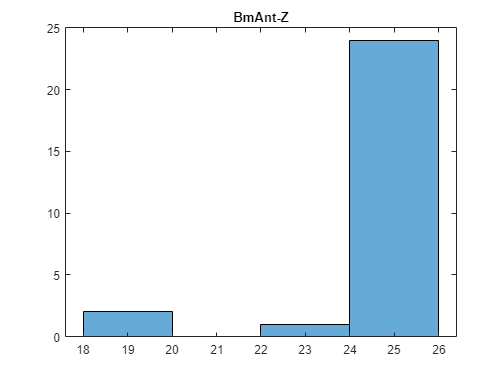

load(outputdir + "BallenyIslands2015\\annotations\\MatchedAnnotations.mat")
annotations = [...
    "BmAnt-A"     ,...
    "BmAnt-B"     ,...
    "BmAnt-Z"     ,...
    "BmD"         ,...
    "Bp20Hz"      ,...
    "Bp20Plus"    ,...
    "BpDwnswp"    ,...
    "BpHigherCall",...
    ];


for i = 1:numel(annotations)

    annT = T(T.Annotation == annotations(i), :);
    F = annT{:, "Frequency"};
    figure
    histogram(F(:, 1))
    title(annotations(i))
end


filterAnn = [
    "Bp20Hz"      ,...
    "Bp20Plus"    ,...
    "BpHigherCall",...
    ];

filterLT = [30, 20, 50];
for i = 1:numel(filterAnn)
    T.Annotation(T.Annotation == filterAnn(i) & T.Frequency(:, 1) > filterLT(i)) = "Unmatched";
end

annotationsBm = [...
    "BmAnt-A"     ,...
    "BmAnt-B"     ,...
    "BmAnt-Z"     ,...
    "BmD"         ,...
    ];

annotationsBp = [...
    "Bp20Hz"      ,...
    "Bp20Plus"    ,...
    "BpDwnswp"    ,...
    "BpHigherCall",...
    ];

Tannotated = T(any(T.Annotation == annotations, 2), :);
TBm = T(any(T.Annotation == annotationsBm, 2), :);
TBp = T(any(T.Annotation == annotationsBp, 2), :);
Tunmatched = T(any(T.Annotation ~= annotations, 2), :);

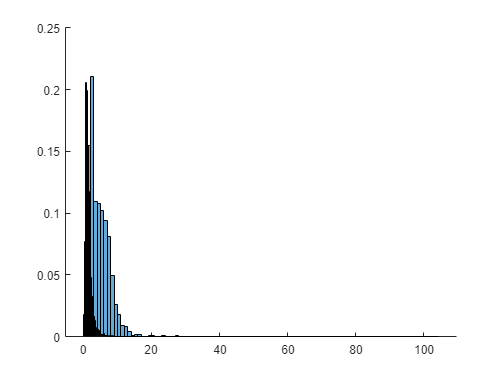

figure
    hold on
        histogram(Tannotated.Duration, "Normalization","probability")
        histogram(Tunmatched.Duration(1:50:end), "Normalization","probability")
    hold off

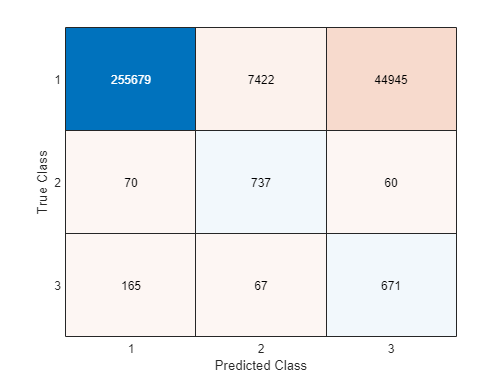

%prepare datamatrix
Xnoise = prepareDataMatrix(Tunmatched);
%Bm blue %Bp fin
Xblue = prepareDataMatrix(TBm);
Xfin = prepareDataMatrix(TBp);
X = [Xnoise;Xblue;Xfin];
%train gmms
GMMblue =   fitgmdist(Xblue, 4, "CovarianceType","full", "RegularizationValue",5e-5);
GMMfin =    fitgmdist(Xfin, 4, "CovarianceType","full", "RegularizationValue",5e-5);
GMMnoise =  fitgmdist(Xnoise(1:10:end, :), 4, "CovarianceType","full", "RegularizationValue",5e-5);

y = [1*ones(size(Xnoise, 1),1);2*ones(size(Xblue, 1),1);3*ones(size(Xfin, 1),1)];
p = [GMMnoise.pdf(X), GMMblue.pdf(X), GMMfin.pdf(X)];
% ey = exp(yhat);
classprobs = p./sum(p, 2);
[conf, yhat] = max(classprobs, [], 2);
confusionchart(y, yhat)

function X = prepareDataMatrix(D)
feats = ["Frequency", "DeltaFrequency", "Power"];
typeidx = [1,2,3,4,5,6,7,8,9]; %med MAD Q1 Q3
standalone  = ["Duration"];
d1 = numel(typeidx)*numel(feats);
d2 = numel(standalone);
X = zeros(size(D, 1), d1 + d2);
for i = 1:numel(feats)
for j = 1:numel(typeidx)
    col = (i-1)*numel(feats) + j;
    X(:, col) = D.(feats(i))(:, typeidx(j));
end
end
for i = 1:d2
    X(:, d1 + i) = D.(standalone(i));
end
% X = (X - mean(X, 1))./std(X, 1);
end